# ModSim Project 3

By Audrey Ip and Dongim Lee

## **Question**

### **Modeling Question and Categorization**

Our modeling question is “How does the amount of clubs someone is in impact their chance of infection?” This is an explanation question because we want to know why the FWOP cold spread so quickly. Specifically, we want to determine whether or not the amount of clubs someone is in impacted the disease’s spread.

### **Importance / Interest**

This question is important because during the Fall 2023 semester at Olin, sickness tends to spread around campus. This year was particularly severe because of the FWOP cold, where a cold spread among those in FWOP during tech week and then infected other students at Olin. Because this disease was mainly propagated by close contact within a club, we want to know how the amount of clubs impacts how likely someone is to be infected.

This question is interesting because during the FWOP cold of Fall 2023, it was widely discussed among the first years, especially since it derailed many DesNat design reviews. It would be in our best interest to know a person’s likelihood of infection so future classwork won’t be inhibited.

### ** Background Information and References**

[https://docs.google.com/spreadsheets/d/1Pic9EbkL2dKK1e7_r3qCNIMHoBNygZ_YDTelcIxoYNE/edit#gid=0](https://docs.google.com/spreadsheets/d/1Pic9EbkL2dKK1e7_r3qCNIMHoBNygZ_YDTelcIxoYNE/edit#gid=0) 

In our model, we distinguish student organizations as project teams or clubs. For the sake of simplicity, project teams are not considered clubs. “Tryhards” refer to the people that are in a project team AND a club. 

To develop this model, we needed to know the Olin student population and the membership counts of various club and project teams. To get the student population, we looked it up on Olin’s website. Student organization memberships were obtained by surveying the leaders and asking members.

## Methodology/Model

### **Description**

Our model has three states: susceptible, infected, and recovered. Susceptible are those who have never been sick, infected are those who have been infected by the disease, and recovered are those who have recovered from the disease.

Because we are focusing on disease spread, we will be focusing on the average amount of infected people, but susceptible and recovered people will be included. People can only be infected if they have a connection to an infected person for that timestep:

- Exposure = infection rate * M * I

- Probability of Infection = exposure / (1 + exposure)

 At each timestep, whether or not a person becomes infected is represented as a weighted coin flip, where they have the aforementioned probability of becoming infected.

#### Assumptions

- Each person can only be a part of one project team – Some people are in multiple project teams. However, most people only stick to one because it usually requires a much larger time commitment than other student organizations. Thus, we decided to assign each person 1 project team at maximum for the sake of simplicity.

- There are only 9 student organizations – There are way more than 9 student organizations at Olin! We only included the largest, regularly meeting clubs in our model, else it would be exceedingly convoluted. The only exception is Sodium, which was added to make Luke happy :)

- No one can be in multiple clubs at once – Many students are a part of multiple clubs. However, not everyone will be actively engaged in all of the clubs they are in, nor does every team meet in person regularly. As a result, we decided to assign each person to 1 club at maximum to account for this.

- Each tryhard is only a part of one other club – Likewise to the assumption of “no one can be in multiple clubs at once,” project teams are a large time commitment and are technically considered a “club” (school club, not club in the context of this model). It’s unreasonable to assume that everyone has the time to participate in that many student organizations at once, which is why each tryhard is only in 1 other club aside from their project team.

- All student organizations included in this model meet regularly – not every club meets regularly, and some meet more often than others. Other times, certain subteams in the organization have separate meetings from the all team ones. However, all of the student organizations in this model meet on a semi-regular basis at minimum (at least once per week), so we decided to assume that every project team and organization meet around the same amount.

- All people within a student organization interact the same amount – It is common for all team meetings to occur, so people will have the opportunity to interact with everyone within the student organization. We will assign everyone the same connection weight for simplicity.

### **Deterministic or Random Quantities**

#### Deterministic

- Initial infected – Because this model is based on the FWOP cold, the disease always starts in FWOP

- Club sizes – Because this model is supposed to represent the FWOP cold of Fall 2023, we used the club/project team sizes in 2023

- Student population – Because some not all student organizations are included, some don’t participate in clubs, and some others are studying abroad, we do not use the full Olin student population. Rather, we used the exact amount of project team or club members in the model

- Number of pods/clubs – Because there are so many student organizations at Olin, we cannot reasonably include all of them. Therefore, we will only use 6 project teams and 3 clubs

#### Random

- Who the tryhards are (uniform) – ⅓ of each project team are tryhards, but they are randomly selected so the same people are not “tryhards” in every realization of the model. Each person has an equal chance of being a tryhard or not

- Which club the tryhards are in (uniform) – clubs are randomly assigned so the amount of tryhards per club varies. Each club member has an equal chance of being assigned to each club, although there are limits set to how many people can be assigned to each club

- Becoming infected in each timestep (Bernoulli) – Because there are only two outcomes with probability p (a changing success rate due to changing exposure), becoming infected is a weighted coin flip, which is characteristic of a Bernoulli distribution

- Recovery in each time step (Bernoulli) – Because there are only two outcomes with probability p (a changing success rate due to changing exposure), recovering is a weighted coin flip, which is characteristic of a Bernoulli distribution. However, because the success rate (recovery rate) is constant, this makes this similar to a geometric distribution

### ** Development**

The following are the parameter values:

- Infection rate

- Recovery rate

- Iv0 

After interviewing various project team leads and club presidents, we learned that BAJA has 25 members, DBF has 20, Formula has 81, PInT has 45, RoboLab has 45, Rocketry has 35, FWOP has 27, OFAC has 70, and Sodium has 7. Thus, our model uses those numbers to assign the “pod” sizes. Anecdotally, many upperclassmen have told us that usually freshmen participate in many project teams their freshman year before narrowing it down to just one, which is why we decided to limit each individual to one project team maximum. 

During the FWOP cold, there was one person who was initially infected in FWOP, so Iv0 corresponds to that. Infection and recovery rate were modified so that the total number of infected people overall fell within the approximate range of people infected by the FWOP cold.

We are specifically focusing on the spread of disease through clubs, so we do not have any connections between people that are not in the same club.

### Creating the Adjacency Matrix

% Setting up the adjacency matrix (350 people)
% - Amount of people in each club
% -- BAJA, DBF, Formula, Lemons, PInT, RoboLab, Rocketry
project_team_names = ["BAJA", "DBF", "Formula", "PInT", "RoboLab", "Rocketry"];
project_team_membership = [25 20 81 45 45 35];
% -- FWOP, OFAC, Sodium
club_names = ["FWOP", "OFAC", "Sodium"];
club_membership = [27 70 7];

% - Randomly determine who the tryhards are; there are a deterministic amount of tryhards
% -- Empty matrix to store number of tryhards in each project team
tryhards_n = zeros(1, length(project_team_membership));

% -- Calculate the number of tryhards
% --- 1/3 of project team members are tryhards
for i = 1:length(project_team_membership)
    tryhards_n(i) = round(project_team_membership(i) * 0.33);
end

% -- Randomly determine who the tryhards are
% --- Empty matrix to store who the tryhards are
tryhards = [];

for i = 1:length(project_team_membership)
    temp = randperm(project_team_membership(i));
    tryhard_temp = (temp <= tryhards_n(i));
    tryhards = [tryhards tryhard_temp];
end

% - All students
allstudents = sum(project_team_membership) + sum(club_membership) - sum(tryhards_n);
M = zeros(allstudents, allstudents); % Set up empty matrix

% - Podding matrices for the clubs
% -- Empty cell to store podding matrices
M_pod_list = {};

% -- Create podding matrices for each project team
for i = 1:length(project_team_membership)
    M_pod_list{i} = 3 * (ones(project_team_membership(i), project_team_membership(i)) - eye(project_team_membership(i)));
end

% Add club pods to total student matrix
% - Empty matrix to store slice beginnings and endings
% -- Will be used to create individuals in multiple clubs
slices_project_team = zeros(2, length(project_team_membership));

% - Add the 10 clubs
for i = 1:length(project_team_membership)

    % Determine the slice beginning
	if i == 1
        slice_begin = 1;
    else
        slice_begin = sum(project_team_membership(1:i-1)) + 1;
    end

    % Determine the slice ending
    slice_end = sum(project_team_membership(1:i));

    % Save the slices
    slices_project_team(:,i) = [slice_begin; slice_end];

	% Add it to the large matrix
	M(slice_begin:slice_end, slice_begin:slice_end) = M_pod_list{i};
end

% Stocks
% - Indices of all the tryhards (in M matrix)
idx_tryhards = find(tryhards==1);

% - People in clubs or a project team
club_or_project_team = sum(project_team_membership) + sum(club_membership) - length(idx_tryhards)

club_or_project_team = 271


% - People in only a club
club_only = sum(club_membership) - length(idx_tryhards)

club_only = 20


% - People in only a project team
project_team_only = sum(project_team_membership) - length(idx_tryhards)

project_team_only = 167


% - People in a project team
project_team_total = sum(project_team_membership)

project_team_total = 251

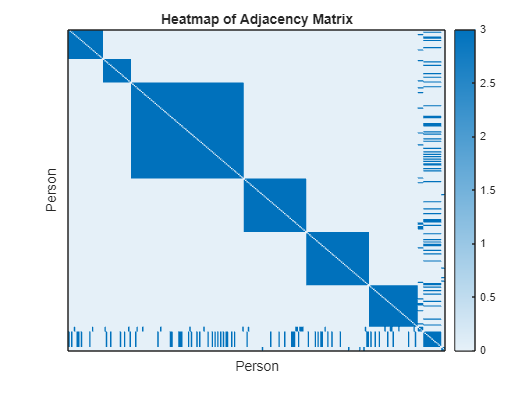


% Assign each tryhard to a club
% - Starting matrices
% -- FWOP, OFAC, Sodium
club_membership = [27 70 7]; % Maximum total people in each club
club_slots_left = club_membership; % Set the slots matrix to be the same as the membership matrix
tryhard_assigned_club = zeros(1,length(idx_tryhards)); % The club each tryhard is in

% - Scramble the indexes of the people in clubs
scrambled_club = randperm(sum(club_membership));

% - Randomly assign each tryhard to a club
for j = 1:length(scrambled_club)

    % Make sure that each club does not exceed the max number of members
    while true
        % Randomly choose a club
        randomclub = randi([1, 3]);
        
        % If there are slots available in the club, break the while loop
        % If there are no slots available, generate another number until a valid number is reached
        if club_slots_left(randomclub) ~= 0
            break
        end
    end

    % Reduce the slots left counter by 1 for the appropriate club
    club_slots_left(randomclub) = club_slots_left(randomclub) - 1;

    % Assign the tryhard to the club
    tryhard_assigned_club(j) = randomclub;
    
end

% - Sorts club membership by index of a person
% -- Persons 1 to 69 are tryhards
% -- Persons 69 to 104 are club-only people
unsorted = [scrambled_club; tryhard_assigned_club]';
sorted_club_membership = sortrows(unsorted, 1);

% Add the non-tryhard club members to the adjacency matrix
% - Find the amount of non-tryhard club members
only_club_members = sorted_club_membership(length(idx_tryhards)+1:max(sorted_club_membership), :);
only_club_members_count = [numel(find(only_club_members==1)), numel(find(only_club_members==2)), numel(find(only_club_members==3))];

% - Add people only in clubs into the adjacency matrix
slices_club = zeros(2,length(club_membership));

for i = 1:length(only_club_members_count)

    % Determine the beginning slice
    if i == 1
        slice_begin = sum(project_team_membership) + 1;
    else
        slice_begin = sum(project_team_membership) + sum(only_club_members_count(1:i-1)) + 1;
    end

    % Determine the slice ending
    slice_end = sum(project_team_membership) + sum(only_club_members_count(1:i));

    % Insert club memberships into the adjacency matrix
    temp_club = 3 * (ones(only_club_members_count(i), only_club_members_count(i)) - eye(only_club_members_count(i)));
    M(slice_begin:slice_end, slice_begin:slice_end) = temp_club;

    % Update the slices matrix
    slices_club(:,i) = [slice_begin; slice_end];

end

% Add connections between people
% - Matrix containing index of a tryhard and the club they are in
sorted_club_membership(1:length(idx_tryhards),1) = idx_tryhards';
sorted_club_membership(length(idx_tryhards)+1:sum(club_membership), 1) = sum(project_team_membership)+1:club_or_project_team;

% - Add connections to the adjacency matrix
for i = 1:length(idx_tryhards)

    % Determine where/who to assign a connection to depending on club
    slice_begin = slices_club(1, sorted_club_membership(i,2));
    slice_end = slices_club(2, sorted_club_membership(i,2));

    % Set the connection 
    M(sorted_club_membership(i,1), slice_begin:slice_end) = 3;
    M(slice_begin:slice_end, sorted_club_membership(i,1)) = 3;

end

% Make sure the diagonal is all 0s
M = M - diag(diag(M));

% - Assert that each club has the proper amount of members
assert(numel(find(tryhard_assigned_club==1)) == club_membership(1), "Wrong number of people in club 1")
assert(numel(find(tryhard_assigned_club==2)) == club_membership(2), "Wrong number of people in club 2")
assert(numel(find(tryhard_assigned_club==3)) == club_membership(3), "Wrong number of people in club 3")

% Create nodeIDs
% - Combined 
org_membership = [project_team_membership only_club_members_count];
org_names = [project_team_names club_names];

% - Empty matrix to store the project team names
nodeIDs = strings ([1, club_or_project_team]);

% -- Fill the nodeIDs matrix
for i = 1:length(org_membership)

    % Determine the slice beginning
    if i == 1
        slice_begin = 1;
    else
        slice_begin = sum(org_membership(1:i-1)) + 1;
    end

    % Determine the slice ending
    slice_end = sum(org_membership(1:i));

    % Set each element in nodesIDs between the slices to the corresponding project team name
    for n = slice_begin:slice_end
        nodeIDs(1,n) = org_names(i);
    end

end

% - Assert that there are right number of students in total
assert(isequal((sum(only_club_members_count) + sum(project_team_membership)), allstudents), 'Wrong number of people')

% Graphing things
% - Heatmap of the adjacency matrix
figure();
heatmap(M)
Ax = gca;
% -- Remove the x and y axes (because they look bad)
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
grid off; % turn off grid
title("Heatmap of Adjacency Matrix")
xlabel("Person")
ylabel("Person")

Figure 1. Displays the connection weight between two different people. Darker blue corresponds to higher connection weight, and lighter blue corrresponds to lower.

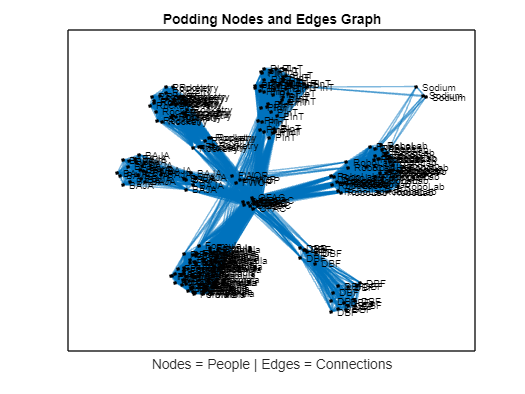

% - Graph the nodes and edges plot
Graph_350 = graph(M);
figure();
h = plot(Graph_350, 'NodeColor', 'k', 'LineWidth', 0.5);
labelnode(h, linspace(1, sum(org_membership), sum(org_membership)), nodeIDs) % Label the nodes according to project team or club
layout(h, 'force', 'WeightEffect', 'inverse')
title('Podding Nodes and Edges Graph')
xlabel('Nodes = People | Edges = Connections')

Figure 2. Displays the connections between people. Higher concentrations of connections clump together, forming "pods".

### **Validation**

In the real world, infection spread is affected by a variety of factors. According to the CDC, length of time, coughing/heavy breathing, symptoms, masks, ventilation/filtration, and distance can all affect someone’s exposure risk. In a club-type setting at Olin, large groups of people are often in close contact with extended periods of time. Take the FWOP cold for example: during tech week (when the disease spread rapidly), people within FWOP were infected at high rates because they spent hours together in an indoor setting while singing and shouting (heavy breathing).This caused the disease to spread to nearly every FWOP member and escape the “pod” it originated in. We can see this behavior in our model, where the disease started in FWOP before spreading to other clubs or project teams through those connected to FWOP (Olin Club Interviews).

Other clubs or project teams also follow this pattern of high exposure. Project teams usually meet indoors at least once a week for hours at a time, so they are in relatively close contact with one another. Other clubs such as OFAC may meet outdoors, but the shared equipment could also spread disease ([source](https://publications.aap.org/pediatrics/article/140/4/e20172477/38139/Infectious-Diseases-Associated-With-Organized?autologincheck=redirected)). 

When someone is in more clubs, they usually have more exposure risk because they interact with a larger group of people. According to Michael Knight, an assistant professor of medicine at George Washington University, “[e]very additional person you’re adding to your pod is [an] increased risk for the whole group” because “there is a greater chance that someone may be exposed” ([source](https://www.washingtonpost.com/lifestyle/wellness/pandemic-pod-winter-covid/2020/10/14/214ed65c-0d63-11eb-b1e8-16b59b92b36d_story.html)). Epidemiologist Stefan Flasche reiterates this, stating that having multiple connections to people outside of your pod allows for “infection chains” to start ([source](https://go.gale.com/ps/i.do?id=GALE%7CA627224634&sid=googleScholar&v=2.1&it=r&linkaccess=abs&issn=22699740&p=AONE&sw=w&userGroupName=act&aty=ip)).

In our model, a higher percent of tryhards were infected than non-tryhards for every timestep in our simulation (except for the very beginning, where the disease originated in a club without many tryhards). Because our model’s clubs/project teams closely resemble pods, the same infection pattern described by Knight and Flasche can be expected. Consequently, those in multiple clubs are more likely to be infected because of increased exposure, which our results indicate.

## Result

### **Metrics/Sweeps**

Our metric is the percentage of infected people for each group of people, which are tryhards and non-tryhards. To account for randomness, we conducted 100 simulations and then derived the average percent of infected people for each group from these simulations.

Our modeling question discusses the chance of infection for different numbers of clubs someone is in, and our metric is directly related to our modeling question, since we divided people into two groups depending on the number of clubs they are in and used the percent of infected people for each group as an indication of the chance of infection.

We conducted a discrete parameter sweep over the number of clubs someone is in, using two distinct cases in our adjacency matrix: tryhards, who are connected to members of two clubs, and non-tryhards, who are connected to members of one club or not connected with anyone.

Regarding the single value approach, our analysis revealed that the percentage of infected tryhards over 100 timesteps is 0.35, while the percentage of infected non-tryhards yielded 0.29. There is a difference in the metrics between tryhards and non-tryhards: the percentage of infected people is 6% higher for tryhards. Moreover, in terms of the distribution, while the general trends are similar in both cases, which is to increase and then decrease, the tryhards’ case has a 2% higher and 6 timesteps earlier peak. For tryhards, the peak has a value of 0.09 and occurs in the 79th timestep, while non-tryhards’ peak has a value of 0.07 and appears in the 85th timestep.

This difference can be attributed to the higher likelihood of tryhards, who are in two clubs(pods), interacting with more people in those clubs, allowing them to be more easily and quickly exposed to disease and get infected.

### **Analysis**

It is more likely that a greater percentage of tryhards are infected than non-tryhards, and the infected tryhards are likely to get infected faster than infected non-tryhards. This is because tryhards, who are in two clubs, are likely to interact with more people in the clubs than non-tryhards, who are in only one club, which accelerates the infection.

% Initial infections
Iv1 = zeros(allstudents,1); Iv1(sum(project_team_membership)+1)=1;
% -- Parameters
infection_rate = 0.001;
recovery_rate = 0.05;
% -- Setting a random seed
rng(101)

% - Running multiple realizations
timesteps = 100;
realizations = 100;
Ih_pods_temp = zeros(realizations,timesteps);
Sh_pods_temp = zeros(realizations,timesteps);
Rh_pods_temp = zeros(realizations,timesteps);
% -- Running the simulation for 150 timesteps 1000 times
count_infected_tryhards = zeros(realizations, 1);
count_infected_others = zeros(realizations, 1);
tryhards_infected = zeros((length(idx_tryhards)*realizations), 100);
others_infected = zeros(((allstudents-length(idx_tryhards))*realizations), 100);
c = 1;
d = 1;
for t = 1:realizations
    count_infected_tryhards(t, :) = 0;
    count_infected_others(t, :) = 0;
	% Run the simulation
	[Sh_pods, Ih_pods, Rh_pods] = simulate_absir(M, Iv1, timesteps, infection_rate, recovery_rate);
    for i = 1:allstudents
        if any(idx_tryhards == i)
            if sum(Ih_pods(i, :)) > 0
                count_infected_tryhards(t, 1) = count_infected_tryhards(t, 1) + 1;
            end
            tryhards_infected(c, :) = Ih_pods(i, :);
            c = c + 1;
        elseif any(idx_tryhards ~= i)
            if sum(Ih_pods(i, :)) > 0
                count_infected_others(t, 1) = count_infected_others(t, 1) + 1;
            end
            others_infected(d, :) = Ih_pods(i, :);
            d = d + 1;
        end
    end
	% Calculate the total amount of infected per timestep and store into a matrix
	Ih_pods_temp(t,:) = sum(Ih_pods,1);
    Sh_pods_temp(t,:) = sum(Sh_pods,1);
    Rh_pods_temp(t,:) = sum(Rh_pods,1);
end
infection_percent_for_tryhards = mean(count_infected_tryhards) / length(idx_tryhards);
infection_percent_for_others = mean(count_infected_others) / (allstudents-length(idx_tryhards));
% -- Calculate the mean amount of infected per timestep with all realizations
I_count_pods = mean(Ih_pods_temp, 1);
S_count_pods = mean(Sh_pods_temp, 1);
R_count_pods = mean(Rh_pods_temp, 1);

% Assert that the sum of the susceptible, infected, and recovered history is a matrix of 1s
assert(isequal((Sh_pods + Ih_pods + Rh_pods), ones(allstudents,timesteps)), 'Pods assertion failed');
disp("Assertions passed!")

Assertions passed!


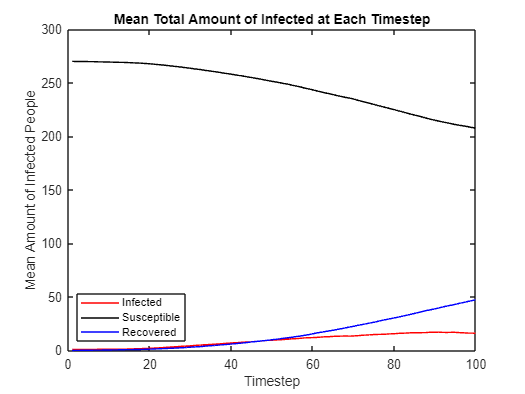

% - Infection count over time graph
figure();
plot(I_count_pods, 'Color', 'red', 'DisplayName', 'Infected'); hold on
plot(S_count_pods, 'Color', 'black', 'DisplayName', 'Susceptible'); 
plot(R_count_pods, 'Color', 'blue', 'DisplayName', 'Recovered'); 
xlabel('Timestep')
ylabel('Mean Amount of Infected People')
title('Mean Total Amount of Infected at Each Timestep')
legend('Location', 'southwest')

Figure 3. Count of each stock simulated over time. Multiple realizations taken to generate a smooth curve.

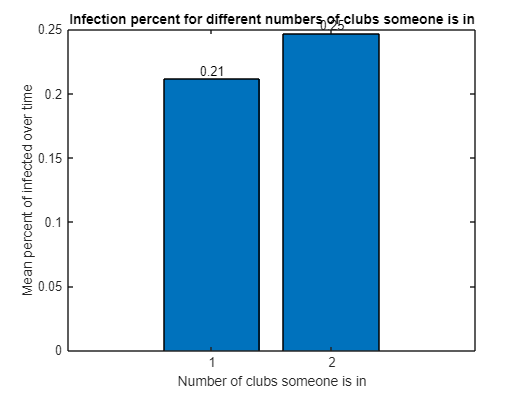

% parameter sweep result
figure()
x=["1"; "2"];
w=[infection_percent_for_others; infection_percent_for_tryhards];
bar(w)
xticklabels(x);
xlabel("Number of clubs someone is in");
ylabel("Mean percent of infected over time");
title("Infection percent for different numbers of clubs someone is in");
text(1,w(1),num2str(w(1)', '%.2f'),'vert','bottom','horiz','center'); 
text(2,w(2),num2str(w(2)', '%.2f'),'vert','bottom','horiz','center'); 

Figure 4. Display mean percent of infected people over time for each group (tryhards and non-tryhards).

% parameter sweep over infection rate
beta_all = linspace(0, 0.01, 100);
counts_infected_tryhards = zeros(realizations, length(beta_all));
counts_infected_others = zeros(realizations, length(beta_all));
progress = waitbar(0, "Calculations in progress");
for j = 1:length(beta_all)
    for t = 1:realizations
	    % Run the simulation
        [~, Ih, ~] = simulate_absir(M, Iv1, timesteps, beta_all(j), recovery_rate);
        for i = 1:allstudents
            if any(idx_tryhards == i)
                if sum(Ih(i, :)) > 0
                   counts_infected_tryhards(t, j) = counts_infected_tryhards(t, j) + 1;
                end
            elseif any(idx_tryhards ~= i)
                if sum(Ih(i, :)) > 0
                  counts_infected_others(t, j) = counts_infected_others(t, j) + 1;
                end
            end
        end
    end
    waitbar(j/100, progress);
end
close(progress);
infection_percents_for_tryhards = mean(counts_infected_tryhards, 1) / length(idx_tryhards);
infection_percents_for_others = mean(counts_infected_others, 1) / (allstudents-length(idx_tryhards));

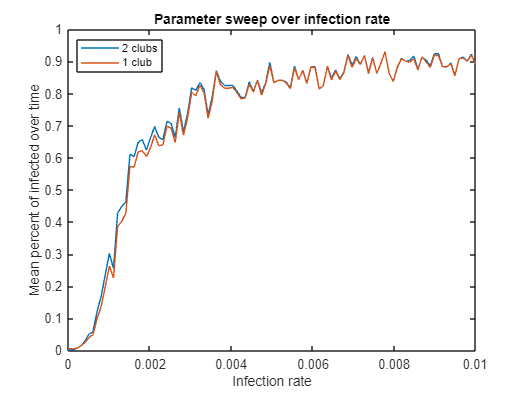

figure()
plot(beta_all, infection_percents_for_tryhards, 'DisplayName', '2 clubs'); hold on;
plot(beta_all, infection_percents_for_others, 'DisplayName', '1 club')
title("Parameter sweep over infection rate")
xlabel("Infection rate")
ylabel("Mean percent of infected over time")
legend("Location", "northwest");

Figure 5. Displays parameter sweep over infection rate from 0 to 0.01

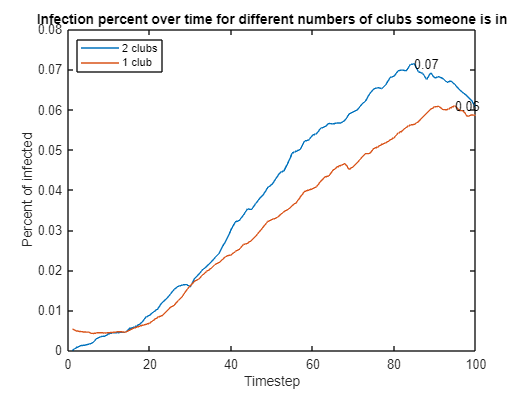

figure()
x=["1 club"; "2 clubs"];
tryhards_plot = sum(tryhards_infected, 1)/(length(idx_tryhards)*realizations);
others_plot = sum(others_infected, 1)/((allstudents-length(idx_tryhards))*realizations);
plot(tryhards_plot, 'DisplayName', '2 clubs'); hold on;
plot(others_plot, 'DisplayName', '1 club')
xlabel("Timestep");
ylabel("Percent of infected");
legend("Location", "northwest");
title("Infection percent over time for different numbers of clubs someone is in")
[max_tryhards, idx_tryhards] = max(tryhards_plot);
[max_others, idx_others] = max(others_plot);
text(idx_tryhards, max_tryhards, num2str(max_tryhards, '%.2f'))
text(idx_others, max_others, num2str(max_others, '%.2f'))

Figure 6. Display infection percent of each group over time.

## Interpretation

### **Therefore**

Our modeling question is: how does the amount of clubs someone is in impact their chance of infection? Our model shows that the peak percentage of infected tryhards is higher and appears faster than that of infected non-tryhards. Based on our model, we can conclude that as someone is in more clubs, the person is more likely to get infected or get infected faster.

### **Limitations and Further Work**

#### Limitations

Our model doesn’t account for the fact that there are a lot of student organizations at Olin, obviously more than 9, which is the number of student organizations we assumed in our model for simplicity. This assumption ignores all other interactions and contacts between students besides those occurring in the nine organizations. If there are other organizations other than the nine that have strong connections among members, then our assumption would not hold.

Additionally, within each organization, people probably do not interact equally with each other since some meet more often and for longer than others, such as within subteams. This fact might affect how people interact and even the result.

Our model also assumes that people can be in at most two student organizations, while, in reality, some students are in multiple project teams and clubs. Our assumption holds when people stick to one or two clubs, but it would not hold for some hard-working students who are actively engaged in several clubs and participate in all meetings.

#### Further Work

- Further work can include more clubs and project teams and even add more detailed connections between those in the same grade, the same dorm building, the same research team, etc. This can better capture reality and increase the accuracy of our model.

- Further work can put different weights on different connections by giving stronger connections for those who interact more. For example, we can set stronger connection weights for people in the same subteams or roommates.

- Instead of limiting the maximum number of clubs to two, further work can let people be in various numbers of clubs based on the actual research or survey and do a continuous parameter sweep over the number of clubs someone is in.